%Experiment with wavelet analysis of groundwater series

%Test dataset is hourly series of groundwater (via Willy Burgess)
%Site: Laksmipur PZ1
%X is time (hours, arbitrary origin)
%Y is groundwater head

clear
close all

disp(' ')

disp(' ')

disp('Wavelet analysis')

Wavelet analysis


## Input data

mode = 0 - use SSA outputs as series; mode = 1 - use raw series

mode = 0;

if mode == 0
% Load pre-whitened series from SSA analysis
outfile = 'SSAV2_PZ3_M100_L.mat';


disp(['Data =  ' outfile])

load(outfile);

% If selecting a certain part of the incoming data edit range as below:
%
%
%
%

% Y = RCdetrend(16000:18500)';
Y = RCdetrend';
N = length(Y);
X = 1:N;

else
% Specify and load input file
[filename,pathname] = ...
  uigetfile('*.csv','Specify input file (2 column CSV format)');
  infile = fullfile(pathname,filename);
  
disp(['Data =  ' filename])

%load data file
fid = fopen(filename,'r');

%skip the header
header_line = fgetl(fid);

%pre-dimension arrays larger than we need 
X = ones(100000,1);
Y = X;

i = 0;
while ~feof(fid)
 i = i + 1;
 line = fgetl(fid);
 comma = strfind(line,',');
 X(i) = str2double(line(1:comma-1));
 Y(i) = str2double(line(comma+1:end));
end

fclose(fid);
N = i;

%trim the X and Y vectors to the data length
X = X(1:N);
Y = Y(1:N);

end

Data =  SSAV2_PZ3_M100_L.mat


## Pre-process data

%series to be analysed is Y, with unit step (= 1 hour)
series_variance = std(Y)^2;


if mode == 1
%Initial QC
figure(1)
subplot(2,1,1)
 plot(X,Y)
 xlabel('Time (hrs)');
 ylabel('Head (mBar)');

%look for spikes or dropouts
minY = 1;  %edit as appropriate
maxY = 150000;

dropouts = find(Y < minY);
spikes = find(Y > maxY);
if ~isempty(dropouts)
 Y(dropouts) = NaN;
end
if ~isempty(spikes)
 Y(spikes) = NaN;
end

subplot(2,1,2)
 plot(X,Y)
 xlabel('Time (hrs)');
 ylabel('Head (mBar)');
 
close  % clear figure

else
 %deal with any gaps in data - pad with mean
 series_mean = mean(Y(~isnan(Y)));
 Y(isnan(Y)) = series_mean;
 
end

## Basic wavelet analysis

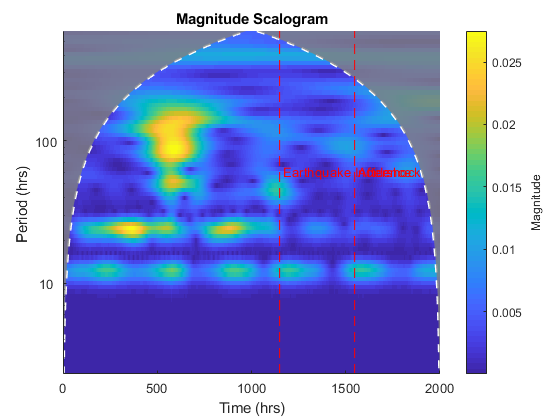

% cwt(Y,hours(1))
hold on; cwt(Y(15500:17500),hours(1)); h = vline(1149, 'r--', 'Earthquake Incidence'); h2 = vline(1547, 'r--', 'Aftershock'); hold off

%hold on; cwt(Y,hours(1)); h = vline(121, 'r--', 'Earthquake Incidence'); hold off
%h2 = vline(1883, 'r--', 'Aftershock');